Projekt 13: ***Wyznaczanie kadencji biegowej na podstawie sygnałów akcelerometrycznych, z  wykorzystaniem funkcji autokorelacji***

Wyznaczanie chwilowej kadencji biegowej/chodu (liczby kroków na minutę) na podstawie  sygnałów przyspieszeń ciała przy pomocy funkcji autokorelacji. Należy zastosować techniki zwiększające rozdzielczość wyznaczania przebiegu kadencji. 

Załadowanie danych projektowych

load sensorlog_20220307_165621.mat

x = Acceleration.X;
y = Acceleration.Y;
z = Acceleration.Z;
timestamp = Acceleration.Timestamp;

% obliczenie różnicy czasowej między próbkami w [s] i częstotliwości
% próbkowania fs [Hz]
dt = seconds(diff(timestamp));
mean_dt = sum(dt)/length(dt);
fs = 1 / mean_dt;
fprintf('Częstotliwość próbkowania wynosi: %.2f Hz', fs)

Częstotliwość próbkowania wynosi: 52.63 Hz

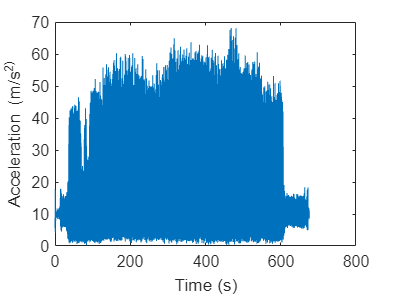


combinedAccel = sqrt(x.^2+y.^2+z.^2);
t = zeros(size(timestamp));


for n = 1 : length(timestamp)
  t(n) = seconds(timestamp(n) - timestamp(1));
end


plot(t, combinedAccel)
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

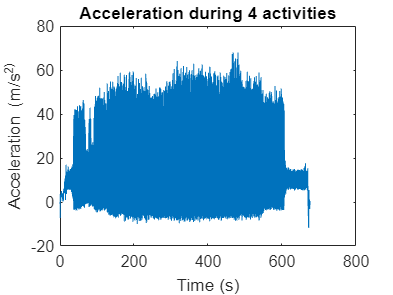

plot (t,x)
title('Acceleration during 4 activities')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

Spektrogram

% Lenght of window
min = log2(16);
max = log2(1024);
window = 2^9

window = 512

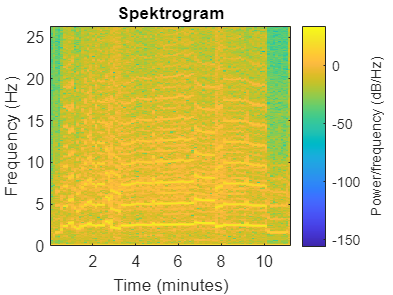

noverlap = int8(0.7*window);
nfft = 1024;
fs1 = fs;
figure,
spectrogram(combinedAccel, window, noverlap, nfft,fs1,'yaxis');  
title("Spektrogram")